clear all
d1=load("precipitation\PPT_zscore.mat");
d2=load("Soil moisture\SM_zscore.mat");
d3=load("L band VOD\VOD_zscore.mat");
d4=load("SIF data\SIF_zscore.mat");
d5=load("SPI weekly\SPI_1month_08_18.mat");


ppt=d1.Z(:,:,1:132);
sm=d2.Z(:,:,1:132);
vod=d3.Z(:,:,1:132);
sif=d4.Z(:,:,1:132);
spi=d5.SPI(:,:,1:132);


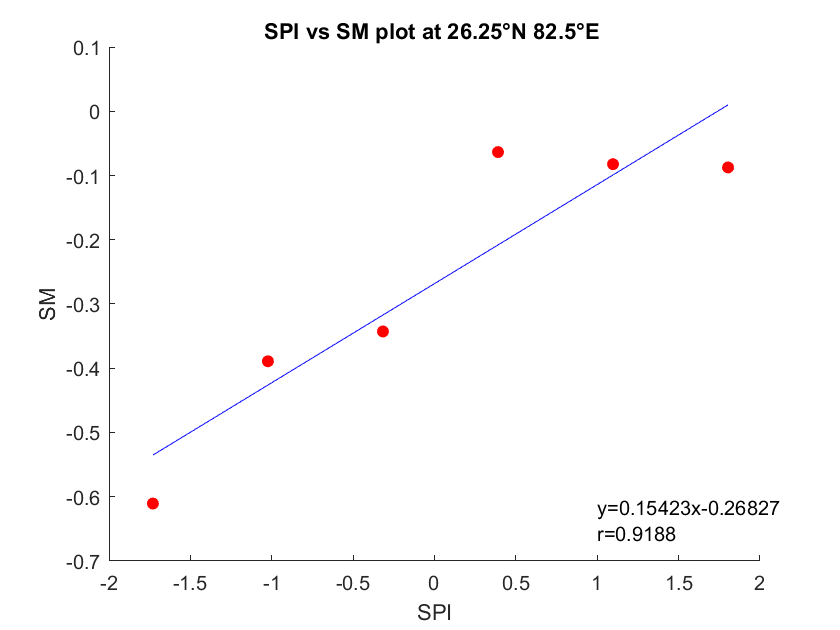

xx="SPI";
yy="SM";
x1=81;
y1=66;
lat=spi(x1,1,1);
long=spi(1,y1,1);

for x = x1              %setting lat values
    for y = y1          %setting long values
        
        X=zeros(132,1);
        Y=zeros(132,1);
        X(:,1)=spi(x,y,:);
        Y(:,1)=sm(x,y,:);
        
        
        xmax=max(X);
        xmin=min(X);
        step_x=(xmax-xmin)/6;
        rangex=[xmin:step_x:xmax]';
        lenr_x=length(rangex);
        
        for i = 2:lenr_x
            X1(i-1,1)=(rangex(i)+rangex(i-1))/2;
        end
        
        %ymax=max(Y);
        %ymin=min(Y);
        %step=(ymax-ymin)/6;
        %range_y=[ymin:step:ymax]';
        %lenr_y=length(range_y);
        y1=[];y2=[];y3=[];y4=[];y5=[];y6=[];
        
        for i=1:132
            if isnan(Y(i)) || isnan(X(i))
                continue;
            elseif X(i)>=rangex(1) & X(i)<rangex(2)
                y1=[y1;Y(i)];
            elseif X(i)>=rangex(2) & X(i)<rangex(3)
                y2=[y2;Y(i)];
            elseif X(i)>=rangex(3) & X(i)<rangex(4)
                y3=[y3;Y(i)];
            elseif X(i)>=rangex(4) & X(i)<rangex(5)
                y4=[y4;Y(i)];
            elseif X(i)>=rangex(5) & X(i)<rangex(6)
                y5=[y5;Y(i)];
            elseif X(i)>=rangex(6) & X(i)<=rangex(7)
                y6=[y6;Y(i)];
            end
        end
        
        Y1=[mean(y1);mean(y2);mean(y3);mean(y4);mean(y5);mean(y6)];
        
        mdl=fitlm(X1,Y1);
        
        intercept=mdl.Coefficients.Estimate(1,1);
        slope=mdl.Coefficients.Estimate(2,1);
        r=sqrt(mdl.Rsquared.Ordinary);
        
        D=slope*X1+intercept;
        
        f1=figure(1);
        scatter(X1,Y1,'red',"filled")
        hold on
        plot(X1,D,"b")
        title(xx+" vs "+yy+" plot"+" at "+num2str(lat)+"°N "+num2str(long)+"°E ");
        xlabel(xx);
        ylabel(yy);
        yt="y="+num2str(slope)+"x"+num2str(intercept)+newline+"r="+num2str(r);
        ylim=get(gca,'ylim');
        xlim=get(gca,'xlim');
        text(xlim(2)/2,ylim(1)/1.1,yt)
        %             clear X1;clear Y1;
        hold off
        
    end
end

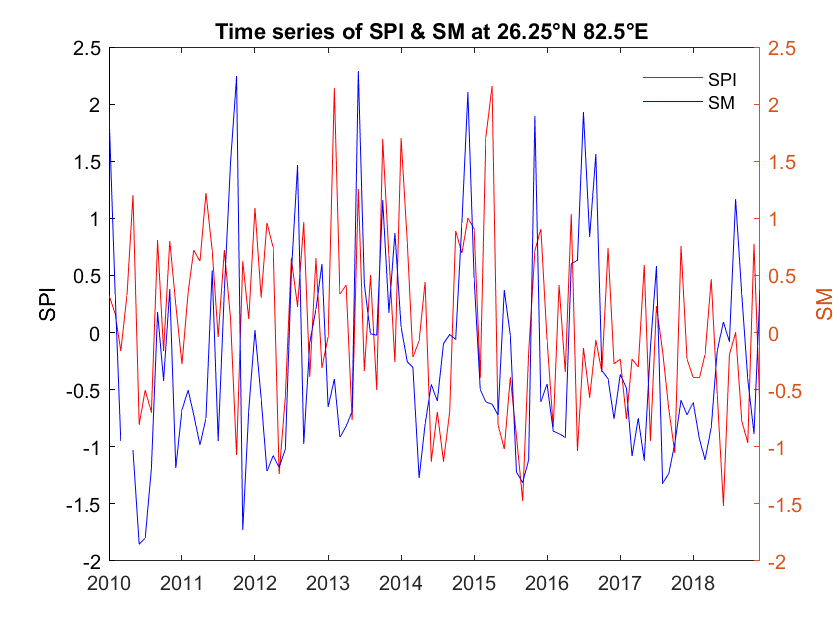

date=squeeze(spi(1,1,:));
%dt=datetime(num2str(date(:)), 'yyyy-MM');
dt =  datetime(fix(date/100),rem(date,100), ones(size(date)), 'Format','MM/dd/yyyy');
%dt = datetime(num2str(date), 'ConvertFrom','yyyy-MM');


f2=figure(2);
plot(dt(25:132),X(25:132),"Color","red");
%ylim([-3 3])
ylabel("SPI")
hold on
yyaxis right
plot(dt(25:132),Y(25:132),"Color","blue");
%ylim([-3 3])
ylabel("SM")
legend(xx,yy);
legend boxoff;
title("Time series of "+xx+ " & "+yy+" at "+num2str(lat)+"°N "+num2str(long)+"°E ");
hold off